**Testing Notebook**

**Kuan-Min Lee**

**Purpose of creating this notebook:**

This notebook is created for intension of testing .m script file of different functions.

**Optimal Gabor Function Testing:**

**Testing of img_spatio_freq.m function:**

**Purpose of building this function:**

**The final prototype of the function will output:**

- **Fast Fourier Transform Plot**

- **Spatial Frequency Mark Out Plot, which will mark out the 10 most dominant spatial frequencies of the image**

- **Most Dominant Wavelength **

- **Other Dominant Wavelengths (the number of the wavelength will be determined by the user in the input parameter)**

- **Most Dominant Angle**

- **Other Dominant Angles (the number of the wavelength will be determined by the user in the input parameter)**

**Testing Scenario 1 (sinusodial signal in one direction (horizontal)):**

**Testing Setting: **

**Image Size: 256*512 **

**Image Content: sin function with wavelength of 20 **

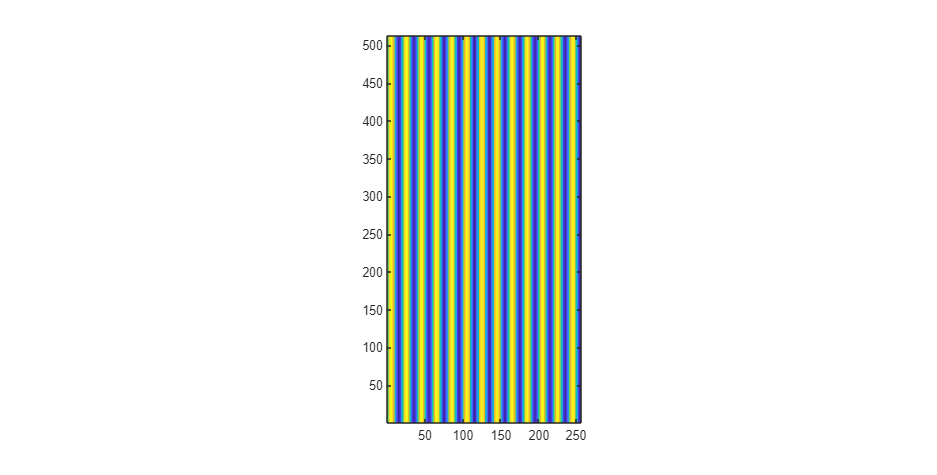

clear all
% create 2D sinusoid image
img_size_x=256; % create an image with size of 256 
lambda=20; % create pattern with wavelength
k=2*pi/lambda; % define k number
x=1:img_size_x; % setup x range
I=sin(1*k*x); % setup sinusoid signal
img_size_y=512; % create an image with size of 256 
x=1:img_size_x; % setup x range
y=1:img_size_y; % setup x range
sin_2d=repmat(I,img_size_y,1);
% imshow(sin_2d)
imagesc(x, y, sin_2d)
axis image
ax = gca;
ax.YDir = "normal";

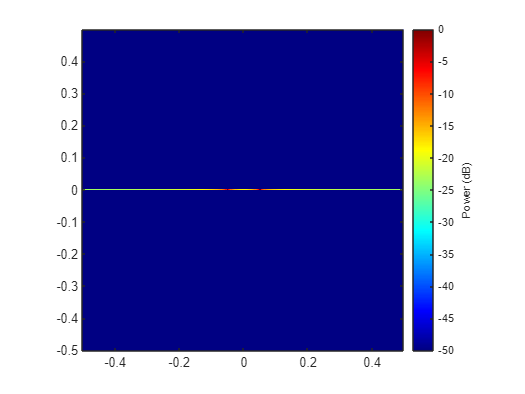

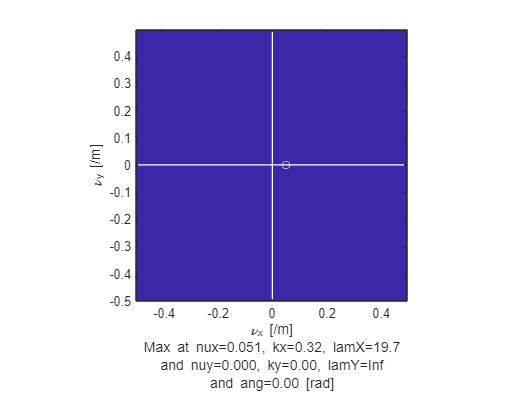

[common_freq, common_wav,common_ang, pks_freq, pks_wav, pks_ang, add_wavs, add_angs]=img_spatio_freq(sin_2d,1,1);

**Testing Scenario 2 (sinusodial signal in one direction (vertical)):**

**Testing Setting: **

**Image Size: 256*256 **

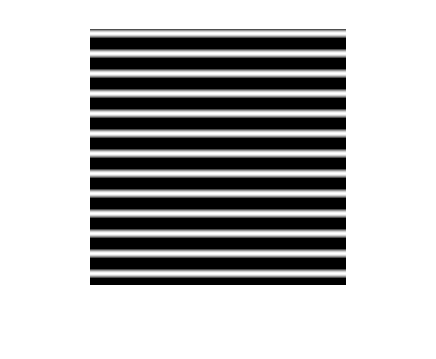

clear all
% create 2D sinusoid image
img_size=256; % create an image with size of 256 
lambda=20; % create pattern with wavelength
k=2*pi/lambda; % define k number
x=1:img_size; % setup x range
I=sin(1*k*x); % setup sinusoid signal
I=transpose(I);
sin_2d_x=repmat(I,1,img_size);
imshow(sin_2d_x)

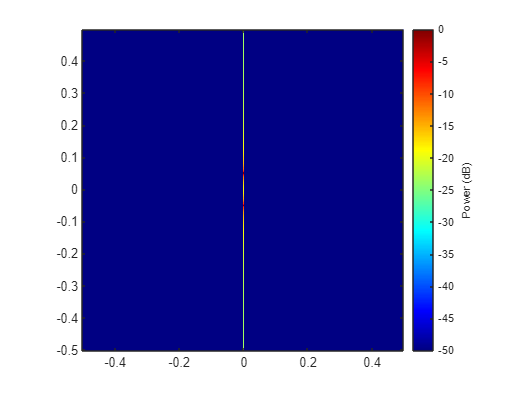

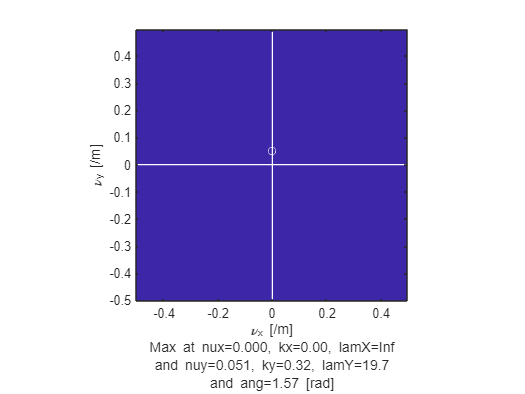

[common_freq, common_wav,common_ang, pks_freq, pks_wav, pks_ang, add_wavs, add_angs]=img_spatio_freq(sin_2d_x,1,1);

**Testing Scenario 3 (sinusodial signal in both direction):**

**Testing Setting: **

**Image Size: 256*384**

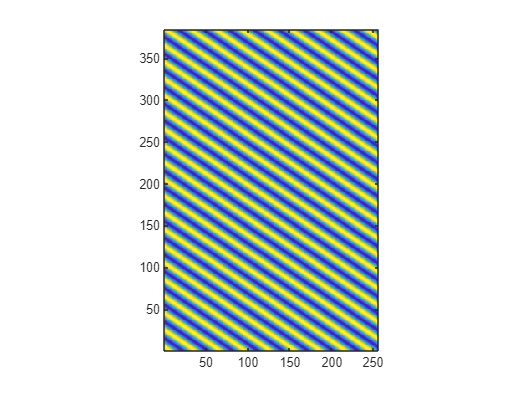

clear all
% create 2D sinusoid image
% clear all;
img_size_x=256; % create an image with size of 256 
img_size_y=384;
lambda_x=30; % create pattern for x
lambda_y=20; % create pattern for y
kx=2*pi/lambda_x; % define kx number
ky=2*pi/lambda_y; % define ky number
x=1:img_size_x; % setup x range
y=1:img_size_y; % setup y range
[gy,gx]=ndgrid(y,x); % setup grid values
I=sin(1*kx*gx+1*ky*gy)+200; % setup sinusoid signal: k = (kx, ky) = (+, +): stripe normal to the oscialltion direction (45 deg)
sin_2d_both=I;
imagesc(x, y, sin_2d_both)
axis image
ax = gca;
ax.YDir = "normal";

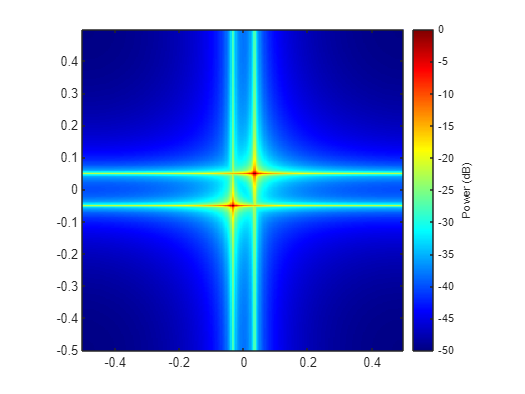

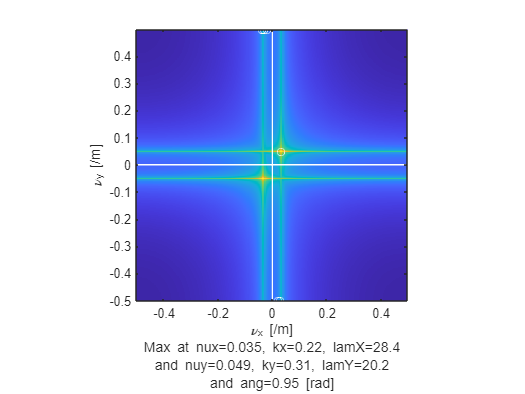

Unrecognized function or variable 'common_freq_both'.

[common_freq, common_wav,common_ang, pks_freq, pks_wav, pks_ang]=img_spatio_freq(sin_2d_both,6,4); % convert the frequency into wavelength

**Finishing the stimulation testing, the img_spatio_freq function will then be utilized as a part of optimal gabor filter functino.**

**Testing of Optimal Gabor filter function:**

**Testing Kobi picture:**

clear all;
k_img=imread("kobi.png"); % insert kobi image (original size: 1224*1632*3)
k_img_resize = imresize(k_img,0.5); % resize the original image to 1/4 of its original size
k_img_resizeGray=im2gray(im2single(k_img_resize)); % convert it to grayscale

**Original Method:**

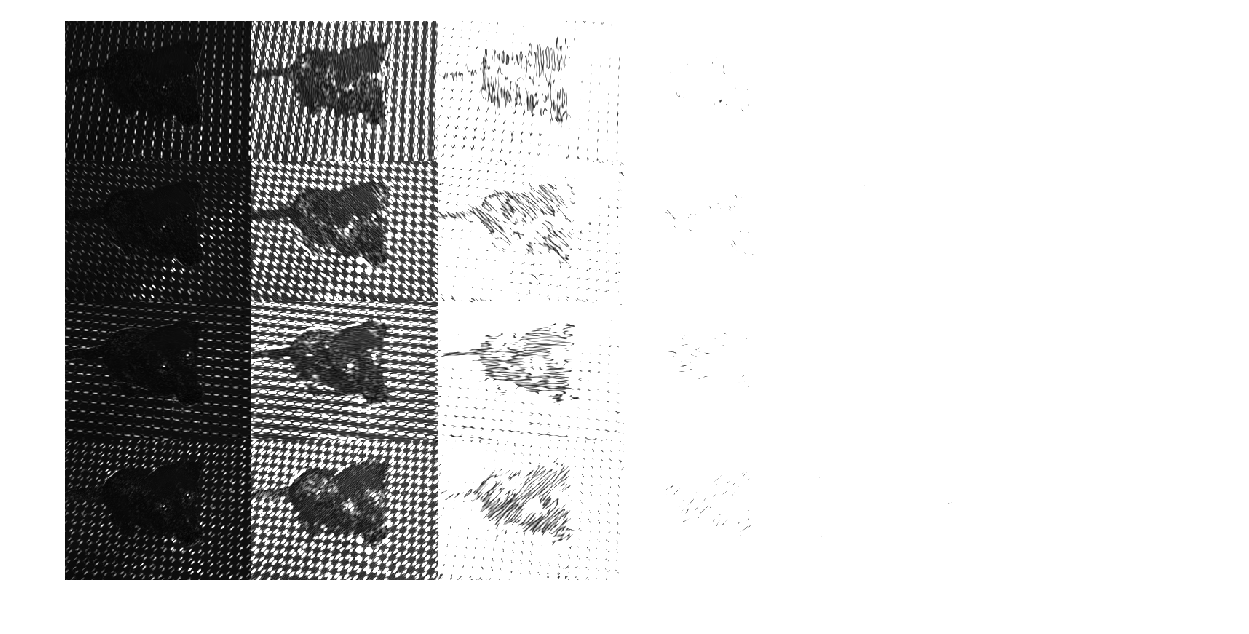

% setup wavelength and angle range
wavelength = 2.^(0:5) * 3;
orientation = 0:45:135;
g = gabor(wavelength,orientation);
% create filterbank
g = gabor(wavelength,orientation);
% visualize gabor filter extraction information
g=gabor(wavelength,orientation);
gabormag=imgaborfilt(k_img_resizeGray,g);
montage(gabormag,"Size",[4 6])

**Utilizing optimal gabor filter:**

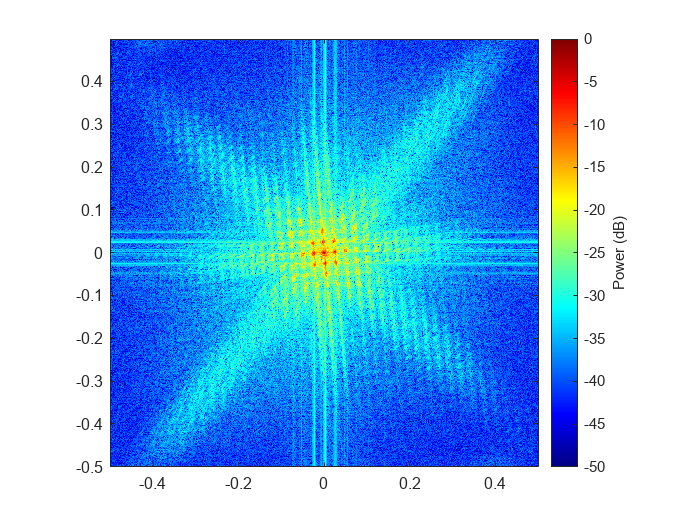

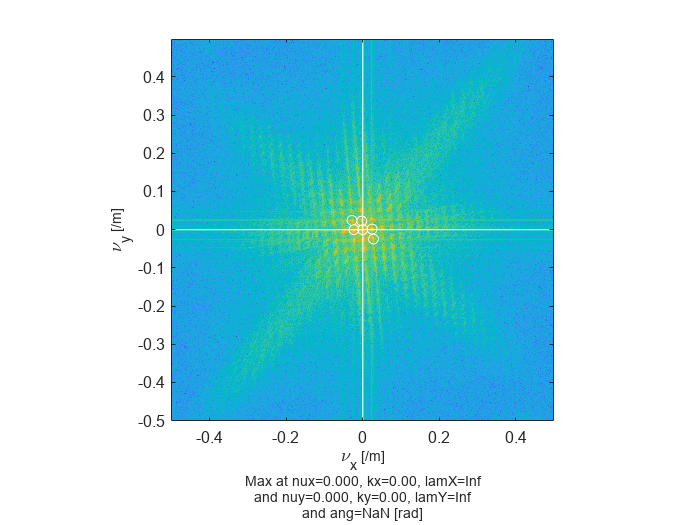

[common_freq,common_wav,common_ang, pks_freq, pks_wav, pks_ang]=img_spatio_freq(k_img_resizeGray,6,4); % convert the frequency into wavelength

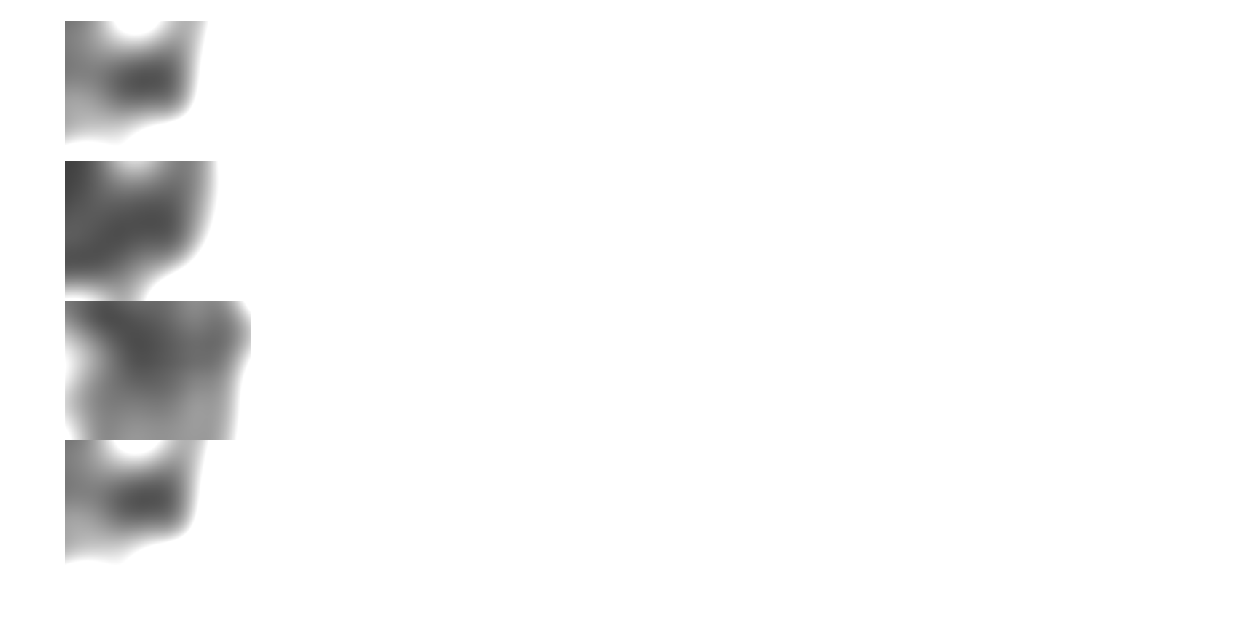

montage(uint8(mag_gabor),"Size",[4 6])

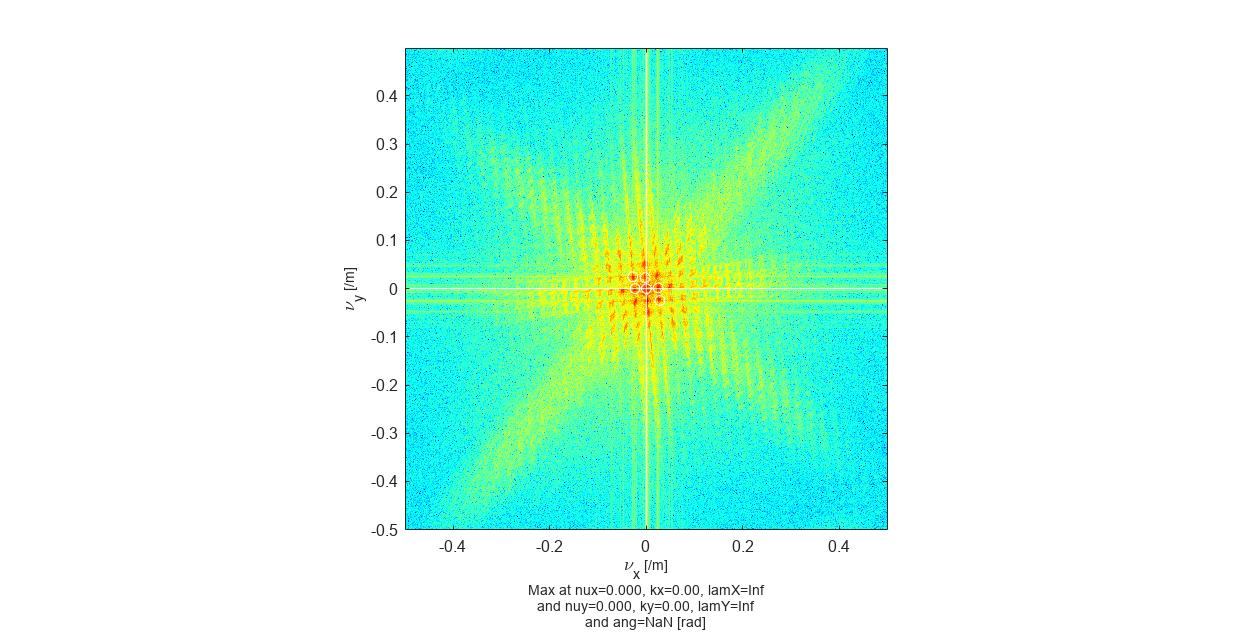

[common_freq,common_wav,common_ang, pks_freq, pks_wav, pks_ang]=img_spatio_freq(k_img_resizeGray,6,4); % convert the frequency into wavelength

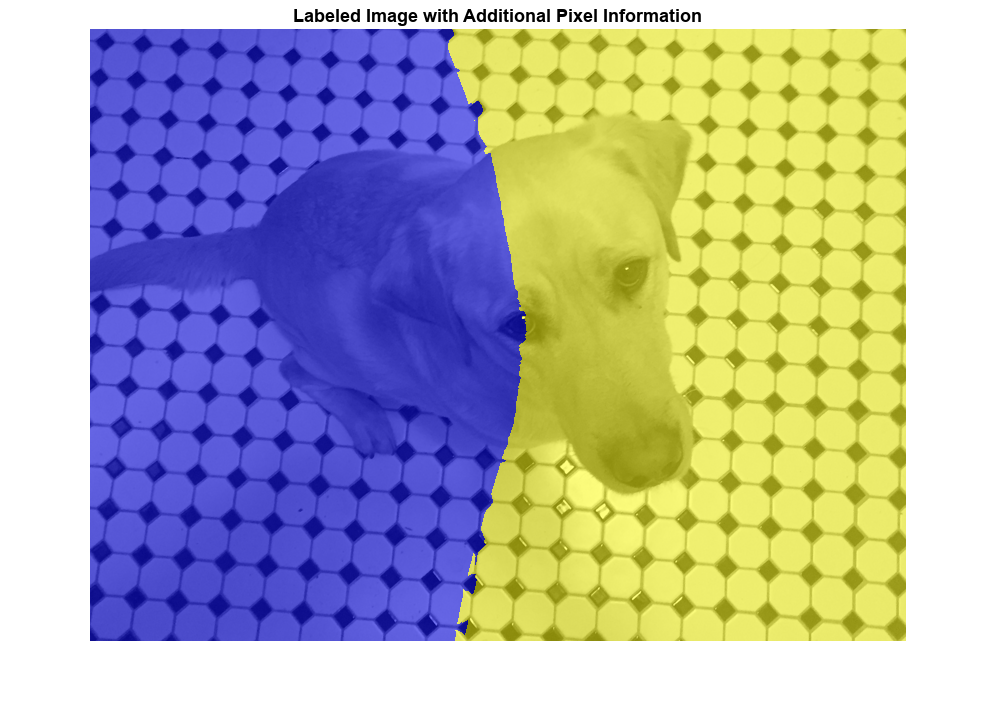

[mag_gabor,phase_gabor]=optimal_gaborfilt(k_img_resizeGray,6,4);